# Bonus Exercise: Anomaly Detection of Coffee Pods

In this section we aim to train an anomaly detector capable of identifying defective coffee pods. The images used are crops of individual pods identified by the YOLOX detector. The dataset is divided into three subsets:

- Training: Contains mostly non-defective ('good') images to train the anomaly detector.

- Calibration: Contains both 'good' and 'bad' images to determine the threshold anomaly score that classifies an object as defective.

- Test: Includes both 'good' and 'bad' images to evaluate the detector's performance.

## Part 1: Data Preparation

### Load and Explore Data

The dataset is pre-organized into training, testing, and calibration folders, with subfolders for 'good' and 'bad' data. We load the images from their respective directories using `imageDatastore`, which facilitates the management of large image datasets. The `LabelSource="foldernames"` option is used to automatically assign labels to the images during data loading, based on the folder names ('good' or 'bad'). We then summarize the labels to verify the distribution of images in each subset. 

addpath(genpath("../Exercise_03/"))
dataDir = "Data/Crops";
normalClass = "good";
anomalyClass = "bad";
dsTrain = imageDatastore(fullfile(dataDir,"train"),IncludeSubfolders=true,LabelSource="foldernames");
summary(dsTrain.Labels)


357×1 categorical

     bad               29 
     good             328 
     <undefined>        0 


dsCal = imageDatastore(fullfile(dataDir,"calibration"),IncludeSubfolders=true,LabelSource="foldernames");
summary(dsCal.Labels)


140×1 categorical

     bad              70 
     good             70 
     <undefined>       0 


dsTest = imageDatastore(fullfile(dataDir,"test"),IncludeSubfolders=true,LabelSource="foldernames");
summary(dsTest.Labels)


140×1 categorical

     bad              70 
     good             70 
     <undefined>       0 


### Visualize Normal vs. Defective Images

In this section, we visualize examples of both 'good' and 'bad' coffee pods from the test dataset. We locate one image of each type and display them side by side using a **montage**, with the title indicating which image has defects. This visualization helps in understanding the visual differences between normal and defective pods.

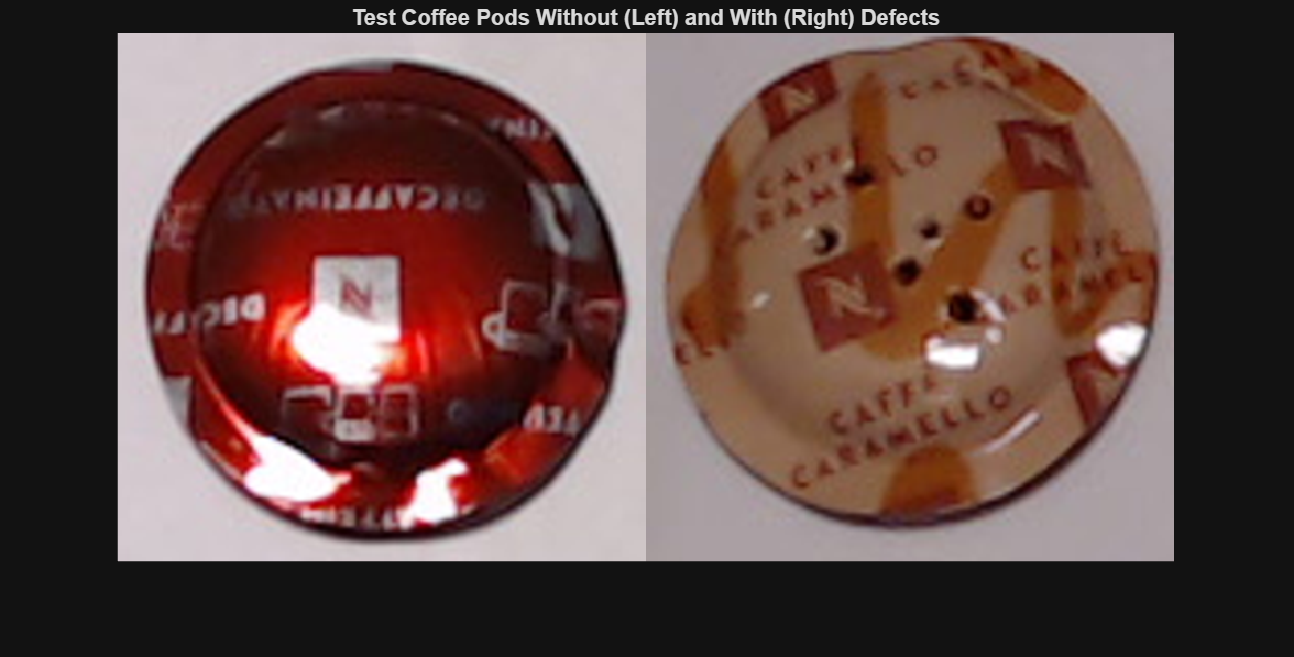

normalImage = find(dsTest.Labels==normalClass,1);
normalImage = read(subset(dsTest,normalImage));
badImage = find(dsTest.Labels==anomalyClass,1);
badImage = read(subset(dsTest,badImage));
montage({normalImage,badImage})
title("Test Coffee Pods Without (Left) and With (Right) Defects")

### Formatting Datastores and Image Augmentation 

In this section, we focus on preparing your data for anomaly detection using MATLAB. The training process requires two distinct datastores: one containing images of normal conditions and the other with images showcasing anomalies. We utilize the [`splitAnomalyData`](https://www.mathworks.com/help/vision/ref/splitanomalydata.html) function to effectively partition the training datastore into these two categories. This separation is crucial for the model to learn distinguishing features between normal and anomalous data.

[dsTrainNormal,dsTrainAnomaly] = splitAnomalyData(dsTrain,anomalyClass, ...
    NormalLabelsRatio=[1 0 0],AnomalyLabelsRatio=[0 1 0],Verbose=false);

To enhance the robustness and generalization capability of the model, we apply random augmentations to the cropped images. This process increases data diversity, allowing the model to better handle variations in real-world scenarios. We achieve this by using the [`transform`](https://www.mathworks.com/help/matlab/ref/matlab.io.datastore.transform.html) function to apply the `augmentADData` augmentation routine on both normal and anomaly datastores.

dsTrainNormal = transform(dsTrainNormal,@augmentADData);
dsTrainAnomaly = transform(dsTrainAnomaly,@augmentADData);

### Visualize Augmented Images

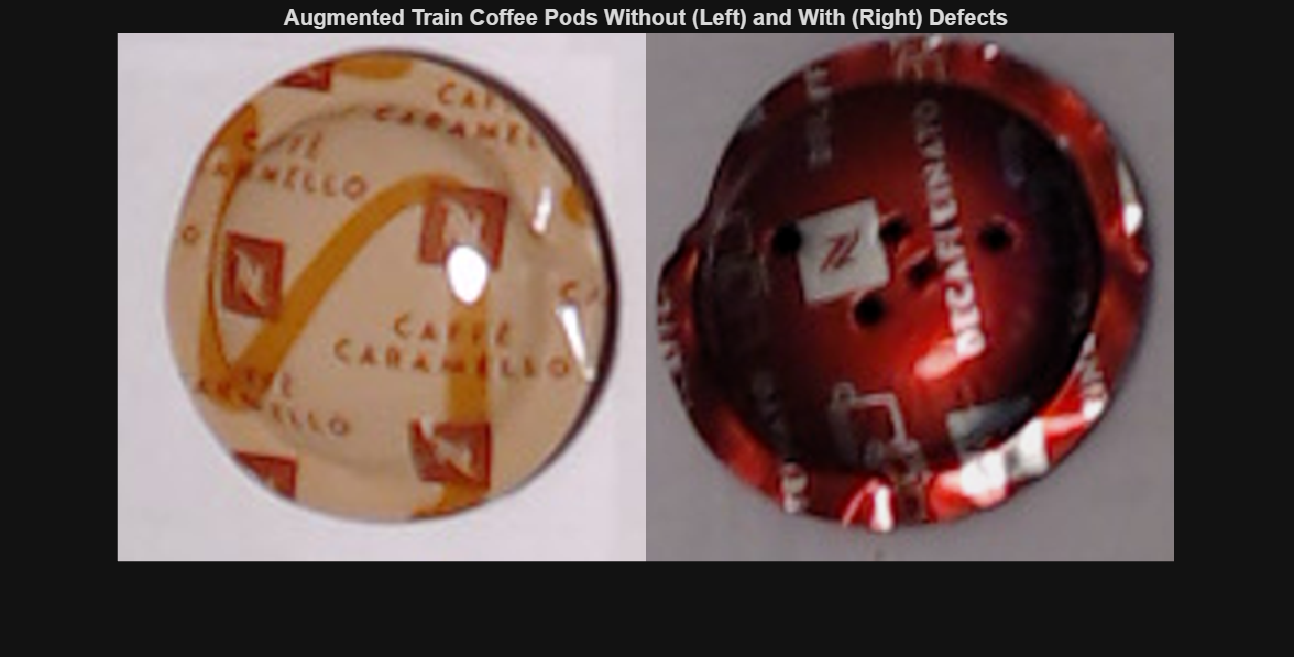

ImagePairNum = 10;
normalImage = read(subset(dsTrainNormal, ImagePairNum));
badImage = read(subset(dsTrainAnomaly,ImagePairNum));
montage({normalImage,badImage})
title("Augmented Train Coffee Pods Without (Left) and With (Right) Defects")

## Part 2: Design the Model

### Initialize FCDD Anomaly Detector

FCDD is an anomaly detection technique that focuses on identifying deviations from normal patterns using a fully convolutional data description network. This approach is effective in detecting localized anomalies within images. We begin by initializing an untrained anomaly detector using the [`fcddAnomalyDetector`](https://www.mathworks.com/help/vision/ref/fcddanomalydetector.html) function, which will be employed to identify anomalies in our dataset.

backbone = pretrainedEncoderNetwork("inceptionv3",3);
untrainedDetector = fcddAnomalyDetector(backbone);

### Train the Anomaly Detector

This section involves training the FCDD anomaly detector using the prepared dataset. If `doTraining` is set to `true`, the detector is trained using the training datasets (dsTrainNormal, dsTrainAnomaly) and the untrained detector (estimated training time ~6min). If training is not performed, an existing trained model is loaded from a file.

doTraining = false;

if doTraining 
    options = trainingOptions("adam", ...
        Shuffle="every-epoch",...
        MaxEpochs=50,...
        InitialLearnRate=1e-4,...
        MiniBatchSize=64,...
        BatchNormalizationStatistics="moving"); %#ok<*UNRCH>
    detector = trainFCDDAnomalyDetector(dsTrainNormal,dsTrainAnomaly,untrainedDetector,options);
    modelDateTime = string(datetime("now",Format="yyyy-MM-dd-HH-mm-ss"));
    save("fcddDetector_" + modelDateTime + ".mat", "detector");
else
    load("fcddDetector.mat")
end

### Set Anomaly Detection Threshold

After training the detector, we predict anomaly scores for the calibration dataset (`dsCal`). The labels are set to identify non-'good' images as anomalies. We visualize these scores using histograms to distinguish between normal and anomalous data. The optimal anomaly detection threshold is computed to maximize the F1 Score, and this threshold is assigned to the detector. Finally, the Receiver Operating Characteristic (ROC) curve is plotted to evaluate the detector's performance.

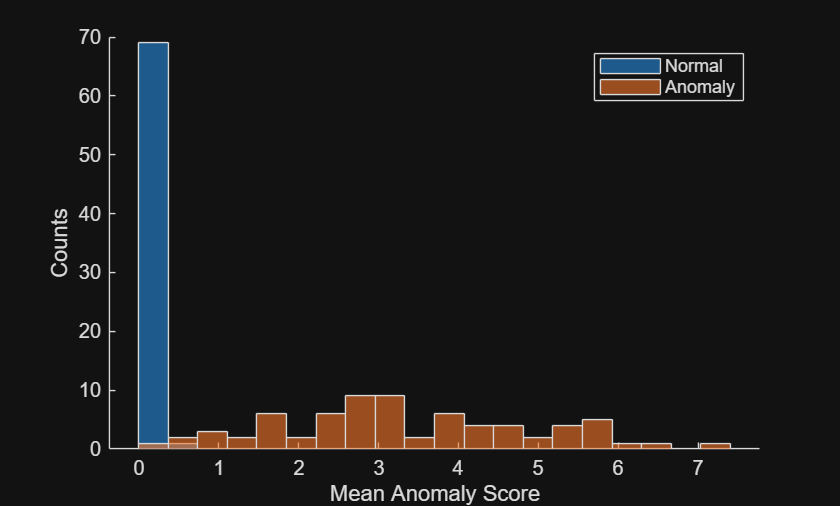

doCalibration = true;

if doCalibration
    scores = predict(detector,dsCal);
else
    load('fcddCalibration.mat')
end

labels = dsCal.Labels ~= "good";
% Visualize the anomaly scores
numBins = 20;
[~,edges] = histcounts(scores,numBins);
figure
hold on
hNormal = histogram(scores(labels==0),edges);
hAnomaly = histogram(scores(labels==1),edges);
hold off
legend([hNormal,hAnomaly],"Normal","Anomaly")
xlabel("Mean Anomaly Score")
ylabel("Counts")

% Compute optimal anomaly threshold
[thresh,roc] = anomalyThreshold(labels,scores,true,"MaxF1Score");
detector.Threshold = thresh;
disp("Optimal Threshold Value =" + thresh)

Optimal Threshold Value =0.28573


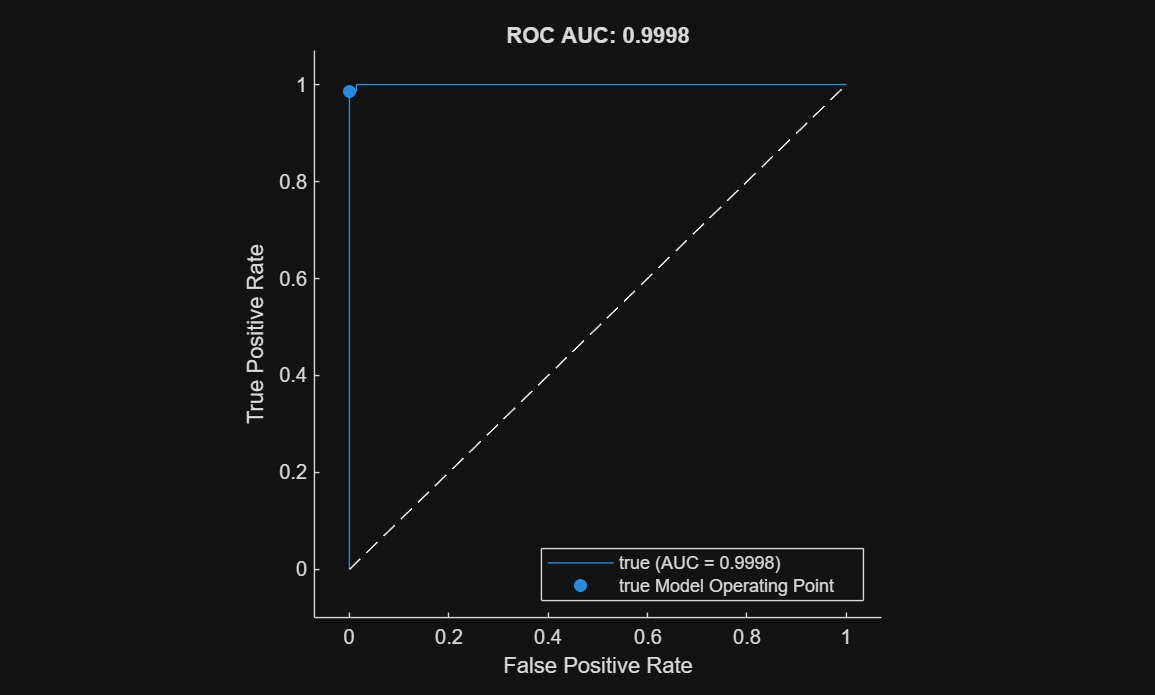

% Plot the roc curve
plot(roc)
title("ROC AUC: "+ roc.AUC)

## Part 3: Evaluate the Model

The model's performance is evaluated using the test dataset (`dsTest`). The detector classifies the test data, and the predicted labels are compared to the actual labels. The [`evaluateAnomalyDetection`](https://www.mathworks.com/help/releases/R2024b/vision/ref/evaluateanomalydetection.html) function calculates various performance metrics such as accuracy, precision, recall, and F1 score. These metrics help assess the model's ability to correctly identify anomalies.

doEvaluation = true;

if doEvaluation
    testSetOutputLabels = classify(detector,dsTest);
    testSetTargetLabels = dsTest.Labels;
    metrics = evaluateAnomalyDetection(testSetOutputLabels,testSetTargetLabels,"bad", Verbose=false);
else
    load('fcddMetrics.mat')
end

### Display Performance Metrics

metrics.DataSetMetrics

ans = 1×8 table
    GlobalAccuracy    MeanAccuracy    Precision    Recall     Specificity    F1Score    FalsePositiveRate    FalseNegativeRate
    ______________    ____________    _________    _______    ___________    _______    _________________    _________________

       0.97143          0.97143        0.98529     0.95714      0.98571      0.97101        0.014286             0.042857     


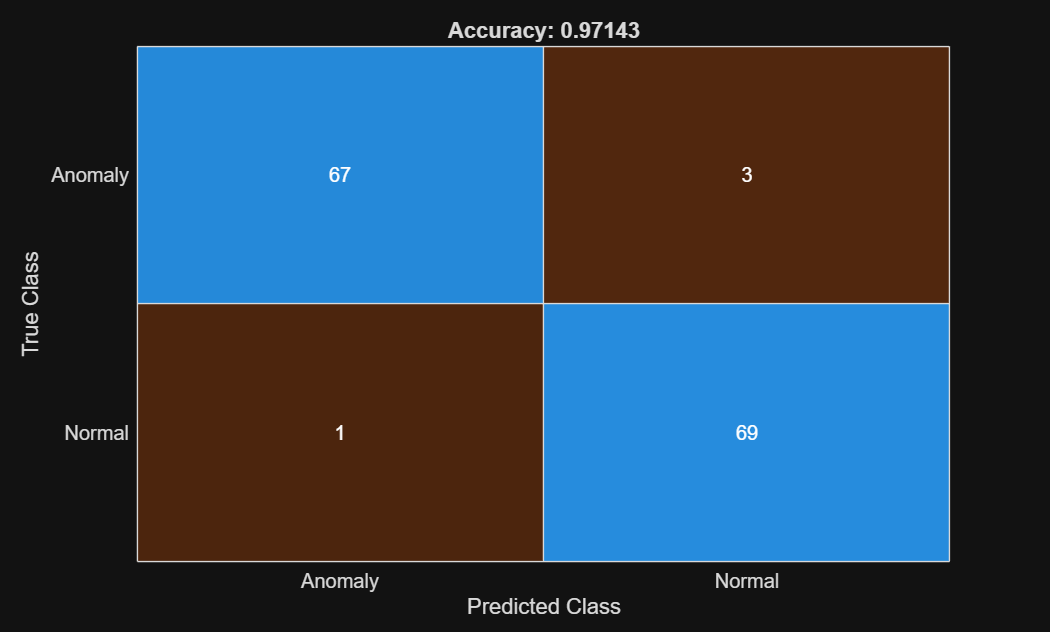

M = metrics.ConfusionMatrix{:,:};
confusionchart(M,["Normal","Anomaly"])
acc = sum(diag(M)) / sum(M,"all");
title("Accuracy: "+acc)

### Interpret Anomaly Detection Resutls

**Determine Display Range for Anomaly Maps**

To interpret the results further, the code calculates the range of anomaly map values across the calibration dataset. This range is used to normalize and display anomaly maps effectively.

calculateRange = true; 

if calculateRange
    minMapVal = inf;
    maxMapVal = -inf;
    reset(dsCal)
    while hasdata(dsCal)
        img = read(dsCal);
        map = anomalyMap(detector,img);
        minMapVal = min(min(map,[],"all"),minMapVal);
        maxMapVal = max(max(map,[],"all"),maxMapVal);
    end
    displayRange = [minMapVal 0.7*maxMapVal];
else
    load('fcddDispRange.mat')
end

#### **View Anomalous Image**

The code identifies a true positive example (an image correctly classified as anomalous) from the test data and overlays the anomaly map on the image for visualization. This helps in understanding the areas identified as anomalous by the detector.

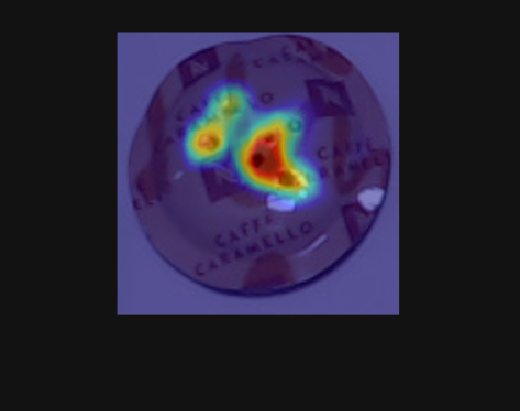

testSetAnomalyLabels = testSetTargetLabels' ~= "good";
idxTruePositive = find(testSetAnomalyLabels & testSetOutputLabels,1);
dsExample = subset(dsTest,idxTruePositive);
imgTP = read(dsExample);
mapTP = anomalyMap(detector,imgTP);
imshow(anomalyMapOverlay(imgTP,mapTP,MapRange=displayRange,Blend="equal"))

#### **View Normal Image**

Similarly, a true negative example (an image correctly classified as normal) is visualized to verify that the detector correctly identifies non-anomalous areas.

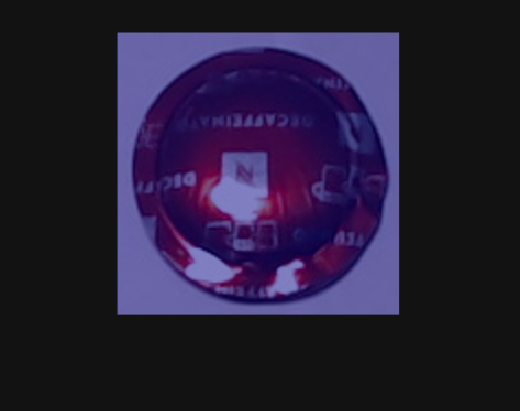

idxTrueNegative = find(~(testSetAnomalyLabels | testSetOutputLabels));
dsExample = subset(dsTest,idxTrueNegative);
imgTN = read(dsExample);
mapTN = anomalyMap(detector,imgTN);
imshow(anomalyMapOverlay(imgTN,mapTN,MapRange=displayRange,Blend="equal"))

#### **View False Anomalous Image**

If any false positives are detected (normal images incorrectly classified as anomalous), they are visualized to understand potential reasons for misclassification.

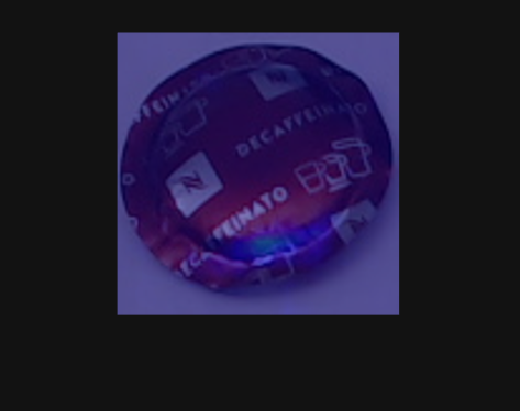

idxFalsePositive = find(~(testSetAnomalyLabels) & testSetOutputLabels);
if ~isempty(idxFalsePositive)
    dsExample = subset(dsTest,idxFalsePositive);
    imgFP = read(dsExample);
    mapFP = anomalyMap(detector,imgFP);
    figure
    imshow(anomalyMapOverlay(imgFP,mapFP,MapRange=displayRange,Blend="equal"));
end

#### **View False Normal Image**

Similarly, any false negatives (anomalous images incorrectly classified as normal) are visualized to assess the model's shortcomings.

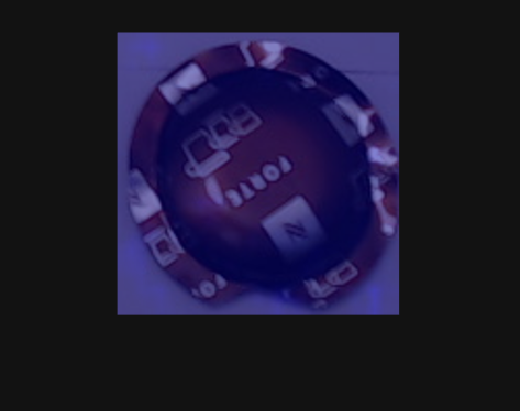

idxFalseNegative = find(testSetAnomalyLabels & (~testSetOutputLabels));
if ~isempty(idxFalseNegative)
    dsExample = subset(dsTest,idxFalseNegative);
    imgFN = read(dsExample);
    mapFN = anomalyMap(detector,imgFN);
    figure
    imshow(anomalyMapOverlay(imgFN,mapFN,MapRange=displayRange,Blend="equal"))
end